# Exploration of Bryce's model for amino acid wing prediction

The question is, can we subtract out the core contributions and approximate the isolated wing free energy change?

The free energy change of dimerization for a given peptide is


$$\Delta F = 2 \Delta F_\textrm{wing} + \Delta F_\textrm{core}$$


where $\Delta F_\textrm{core} = \Delta F_\textrm{NDI}$ or $\Delta F_\textrm{core} = \Delta F_\textrm{PDI}$.  Therefore subtracting two free energies with identical side chain chemistries gives,


$$\Delta F_\textrm{cores} = \Delta F_\textrm{PDI} - \Delta F_\textrm{NDI}$$


Let's start by figuring out average, standard deviation, and standard error for this computation, to see if there's any chance of being able to isolate this--in principle, it should be the same for every pair of identical side chain chemistries.

predData = 'predictions.csv';

predictions = importdata(predData)

predictions =         data: [9826x4 double]
    textdata: {9827x5 cell}


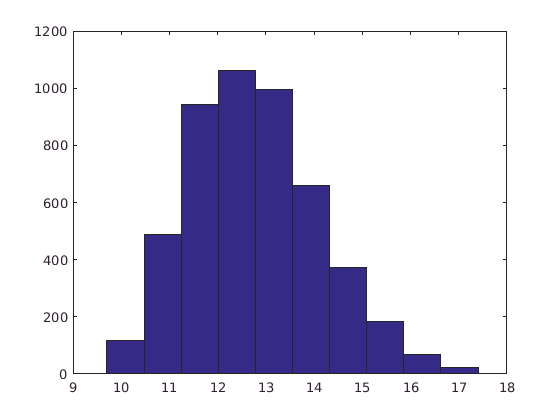


df2 = [-22.3 -11.8 -24 -8.1 -22.1 -21.8 -9 -27.3 -21.3 -25.8 -23.2 -21.8 -32 -22.2 -51.2 -30.4 -26.1 -83.4 -31.2];
sdf2 = [1.6 2.4 3.2 2.1 2.8 2.8 2.1 3 2.3 2.1 2 2.3 3.8 7.1 5.3 2.6 4.6 9.2 3.6];
df3 = [-25.5 -15.9 -30.6 -7.6 -25.3 -34.9 -17.8 -21.2 -22.8 -29.1 -25.4 -30.1 -27 -30.5 -103.5 -36.5 -40.3 -91.8 -49.6];
sdf3 = [3.2 6 3.9 1.9 3.2 4 3.6 2.9 3.3 5.2 3.2 4.9 4.6 3.9 38.5 7.9 6.8 28.9 4.2];
dfn = df3;
sdfn = sdf3;
align = [0.584 0.016 0.303 0.021 0.537 0.268 0.02 0.348 0.245 0.579 0.64 0.016 0.272 0 0.269 0.6 0.468 0.037 0.139];
salign = [0.039 0.007 0.039 0.016 0.042 0.042 0.006 0.033 0.014 0.048 0.072 0.005 0.048 0 0.021 0.085 0.047 0.01 0.02];
preds = predictions.data;
predsNDI = preds(1:2:end,1);
predsPDI = preds(2:2:end,1);
hist(predsNDI-predsPDI)

fprintf('The mean difference is %f +/- %f\n',mean(predsNDI-predsPDI),std(predsNDI-predsPDI))

The mean difference is 12.765637 +/- 1.345214


Okay, this standard deviation isn't too bad -- only a few kT.

So can we remove the core contributions then?  Well, you could do a dimer PMF to compute the isolated NDI/PDI contributions, possibly?

Without doing that, you can still take a look at DFAG, maybe.

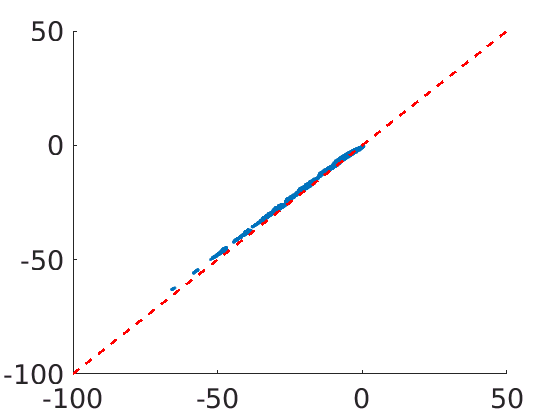

dfagndi = -8.2689;
dfagpdi = -23.5174;
opv3 = 3; %somewhat questionable but let's try it
DFAGtail = -2; %also rather questionable but let's say this is our approximation
ndi = dfagndi-2*DFAGtail;
pdi = dfagpdi -2*DFAGtail;
%range of values you get--in principle you should be able to compare the NDI with the PDI
tails1 = (predsNDI-ndi)/2;
tails2 = (predsPDI-pdi)/2;
figure()
hold on
set(gca,'fontsize',20)
plot(tails1,tails2,'.')
plot(-100:50,-100:50,'r--','linewidth',2)

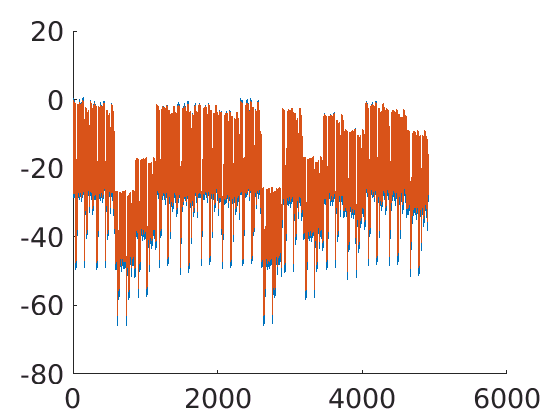


figure()
hold on
set(gca,'fontsize',20)
plot(tails1)
plot(tails2)

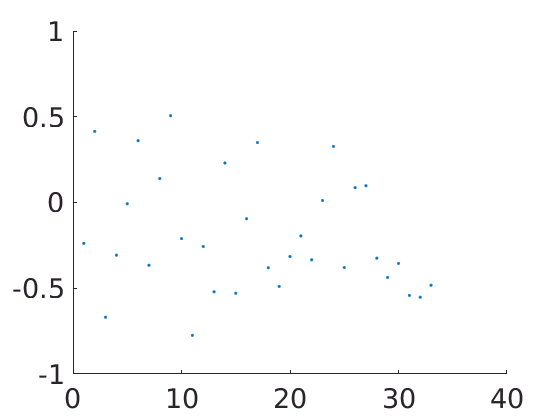

labelsndi = predictions.textdata(2:2:end,1);
labelspdi = predictions.textdata(3:2:end,1);
nonsticky1 = tails1(mean([abs(tails1) abs(tails2)],2)<0.9);
%nonsticky2 = tails2(abs(tails2)<0.9);
labels1 = labelsndi(mean([abs(tails1) abs(tails2)],2)<0.9);
%labels2 = labelspdi(abs(tails2)<0.9);
figure()
hold on
set(gca,'fontsize',20)
plot(nonsticky1,'.')

## Improved Estimates from PMF calculations

We have now performed dimer PMFs for the stripped NDI and PDI cores as used in Bryce's paper.  Let us compute the overall change in free energy for each one and check that the difference between them makes sense with the earlier calculations.

Don't forget to remove the entropic contribution!

**NDI Cores**

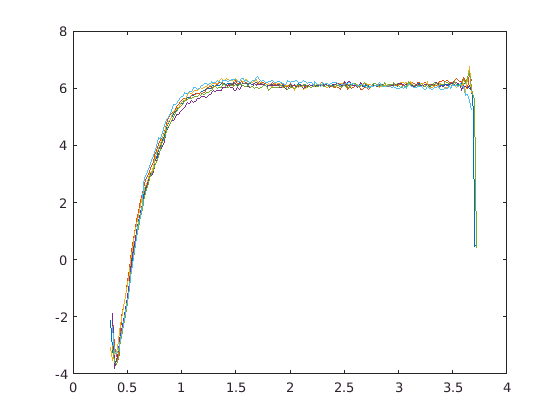

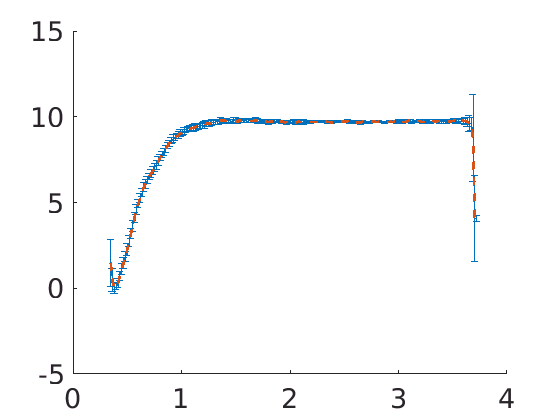

addpath('/home/rachael/Analysis_and_run_code/analysis/coarsegraining/model_assessment');
addpath('/home/rachael/Analysis_and_run_code/analysis/coarsegraining/patchy_particles/helper_functions');
wdirb = '/home/rachael/cluster/scratch/ramansbach/corePMFs/NDI';
%minmaxxs = zeros(6,2);
tstart = 1000;
tinterval = 3800;
tend = 20000;
remove_entropic = 1;
wdir = [wdirb '/5_umbrella'];
[profNDI,errsNDI] = run_block_PMFs(wdir,tstart,tinterval,tend,remove_entropic,[2 3.5 2 3.5 2 3.5 2 3.5 2 3.5]);

**PDI Cores**

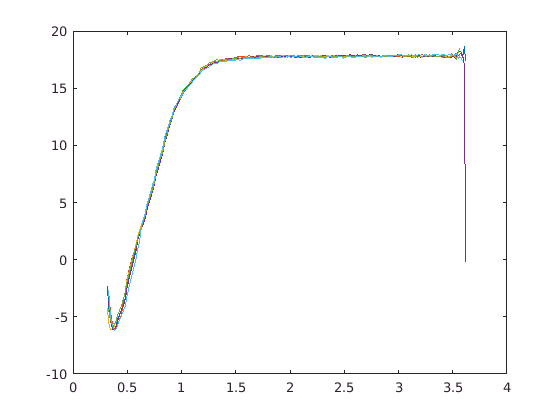

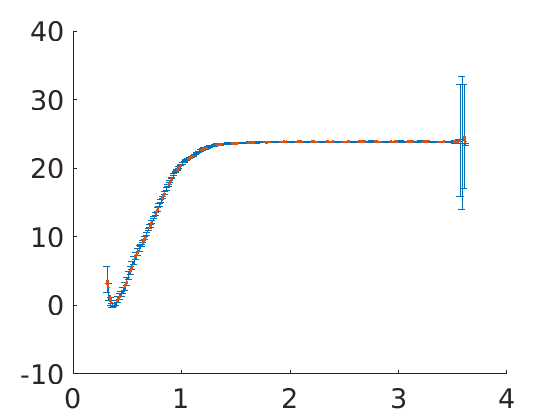

addpath('/home/rachael/Analysis_and_run_code/analysis/coarsegraining/model_assessment');
addpath('/home/rachael/Analysis_and_run_code/analysis/coarsegraining/patchy_particles/helper_functions');
wdirb = '/home/rachael/cluster/scratch/ramansbach/corePMFs/PDI';
%minmaxxs = zeros(6,2);
tstart = 1000;
tinterval = 3800;
tend = 20000;
remove_entropic = 1;
wdir = [wdirb '/5_umbrella'];
[profPDI,errsPDI] = run_block_PMFs(wdir,tstart,tinterval,tend,remove_entropic,[2 3.5 2 3.5 2 3.5 2 3.5 2 3.5]);

All right, this looks pretty good, so now let's estimate the drop for each one.

Take the mean over 2 - 3.5 and subtract the minimum.

Then the error in the maximum (mean over 2-3.5) is the sum-squared-error/number of points

And there's just one error associated with the minimum.

Make it a little easier on yourself and just pick delta F(3 nm) and subtract the minimum and sum the two errors.

minNDI = min(profNDI(:,2));
eminNDI = errsNDI(profNDI(:,2)==min(profNDI(:,2)));
maxNDI = profNDI(abs(profNDI(:,1)-3)==min(abs(profNDI(:,1)-3)),2);
emaxNDI = errsNDI(abs(profNDI(:,1)-3)==min(abs(profNDI(:,1)-3)));
dFNDI = maxNDI - minNDI;
edFNDI = sqrt(eminNDI^2+emaxNDI^2);

minPDI = min(profPDI(:,2));
eminPDI = errsPDI(profPDI(:,2)==min(profPDI(:,2)));
maxPDI = profPDI(abs(profPDI(:,1)-3)==min(abs(profPDI(:,1)-3)),2);
emaxPDI = errsPDI(abs(profPDI(:,1)-3)==min(abs(profPDI(:,1)-3)));
dFPDI = maxPDI - minPDI;
edFPDI = sqrt(eminPDI^2+emaxPDI^2);

ddFcores = dFPDI - dFNDI;
eddFcores = sqrt(edFNDI^2+edFPDI^2);

fprintf('dF for NDI cores is %f +/- %f\n',dFNDI,edFNDI);

dF for NDI cores is 9.676625 +/- 0.317810


fprintf('dF for PDI cores is %f +/- %f\n',dFPDI,edFPDI);

dF for PDI cores is 23.892868 +/- 0.253846


fprintf('Difference in core dFs: %f +/- %f\n',ddFcores,eddFcores);

Difference in core dFs: 14.216243 +/- 0.406744


Okay, 14.2 +/- 0.2 isn't identical but does overlap 13 +/- 1 within error bars, so it looks like these are pretty decent estimates and make sense to fold into the predicted dimerization energies.

Let's just sanity check this with the DFAG SC estimate:

dfagndi = -8.2689;
dfagpdi = -23.5174;
adfag1 = (dfagndi - -dFNDI)/2;
adfag2 = (dfagpdi - -dFPDI)/2;
fprintf('First approximation for DFAG: %f\n',adfag1);

First approximation for DFAG: 0.038313


fprintf('Second approximation for DFAG: %f\n',adfag2);

Second approximation for DFAG: -0.003566


Well, we're a bit off here, but we don't necessarily trust this estimate a lot anyway, and we're at least not TERRIBLY off, although we get somewhat different estimates depending on which tail we're looking at, which suggests maybe using an AND?  throw in an estimate that fits from either PDI or NDI core?

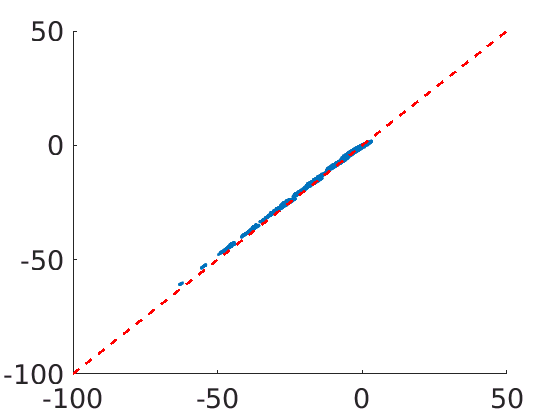

ndi = -dFNDI;
pdi = -dFPDI;
%range of values you get--in principle you should be able to compare the NDI with the PDI
tails1 = (predsNDI-ndi)/2;
tails2 = (predsPDI-pdi)/2;
figure()
hold on
set(gca,'fontsize',20)
plot(tails1,tails2,'.')
plot(-100:50,-100:50,'r--','linewidth',2)

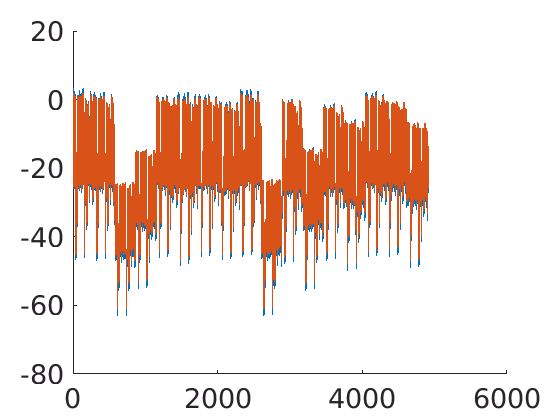


figure()
hold on
set(gca,'fontsize',20)
plot(tails1)
plot(tails2)

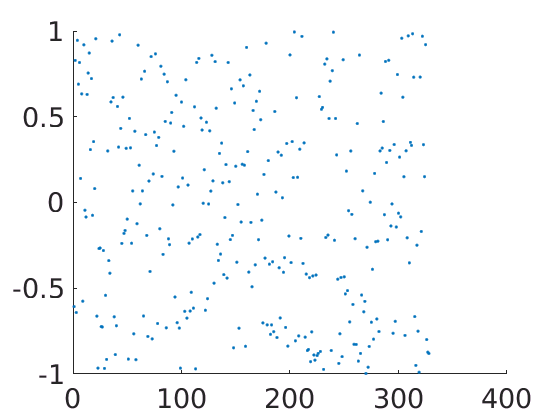

labelsndi = predictions.textdata(2:2:end,1);
labelspdi = predictions.textdata(3:2:end,1);
%nonsticky1 = tails1(mean([abs(tails1) abs(tails2)],2)<0.9);
nonsticky1 = tails1(abs(tails1)<1);
nonsticky2 = tails2(abs(tails2)<1);
%labels1 = labelsndi(mean([abs(tails1) abs(tails2)],2)<0.9);
labels1 = labelsndi(abs(tails1)<1);
labels2 = labelspdi(abs(tails2)<1);
figure()
hold on
set(gca,'fontsize',20)
plot(nonsticky1,'.')

plot(nonsticky2,'x')